# **디지털신호처리 ****HW#2**

Due date : 2021.12.22. 23:59

**이름**** : 고상훈**

**학번**** : 201710868**

아래 문제에 대하여 MATLAB으로 구현하고 mlx파일을 본인의 Github에 업로드 하고 링크 주소를 적으세요.

**Repository 링크 :  https://github.com/kosanghun99/Digital_Signal_Processing_2.git**

1. 이산 비주기 신호 $x\left\lbrack n\right\rbrack =\left\lbrace \underset{\uparrow }{1} ,2,2,1\right\rbrace$에 대하여 다음을 구하라.

1) 4점 DFT 및 IDFT를 수행하라. 그리고 DFT의 결과를 DTFT와 비교하라. 

%%DFT
x = [1,2,2,1];
N = 4;
n = 0:3;
X = dft(x,N);
%DFT 수행 이후 값
X

X =    6.0000 + 0.0000i  -1.0000 - 1.0000i   0.0000 - 0.0000i  -1.0000 + 1.0000i


% DFT 수행 이후의 크기와 위상을 나타내어 보았다.
magX = abs(X)

magX =     6.0000    1.4142    0.0000    1.4142


angX = angle(X)*180/pi

angX =          0 -135.0000  -90.0000  135.0000


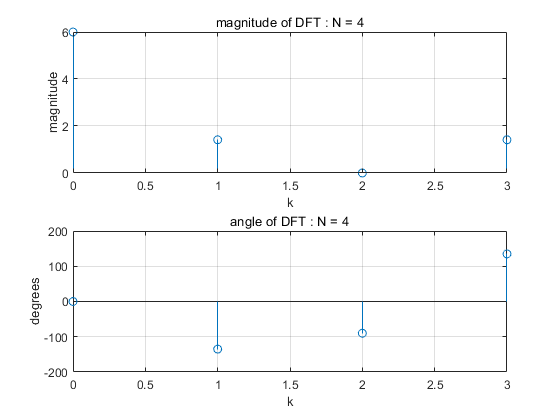

%DFT Figure
figure()
subplot(2,1,1), stem(n, magX);
grid on;
title("magnitude of DFT : N = 4");
xlabel("k");
ylabel("magnitude");
subplot(2,1,2), stem(n, angX);
title("angle of DFT : N = 4");
xlabel("k");
ylabel("degrees");
grid on;

%% IDFT 수행
inverse_x = idft(X,N);
% IDFT 수행 이후 값
inverse_x
% IDFT의 수행이후 크기와 위상을 나타내어 잘 복원되었는지 확인해보았다.
magx = abs(x)

magx =      1     2     2     1


angx = angle(x)*180/pi

angx =      0     0     0     0


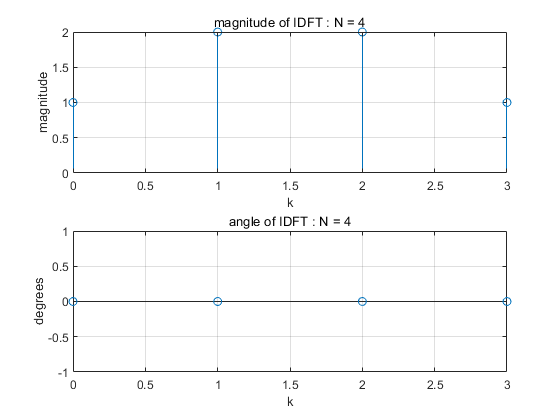

%IDFT Figure
figure()
subplot(2,1,1), stem(n, magx);
grid on;
title("magnitude of IDFT : N = 4");
xlabel("k");
ylabel("magnitude");
subplot(2,1,2), stem(n, angx);
title("angle of IDFT : N = 4");
xlabel("k");
ylabel("degrees");
grid on;

clear all

DFT의 결과를 DTFT와 비교하여 보았다.

DTFT 식의 정의를 이용한다면 이는 이산 비주기 신호이기 때문에 유한 신호라 생각할 수 있고, 식에 대입해본다면

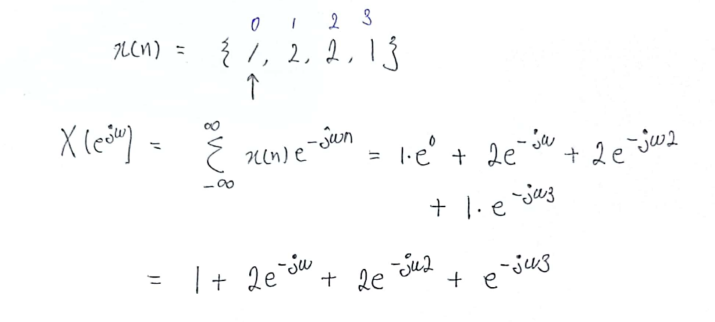

이를 matlab으로 표현해본다면

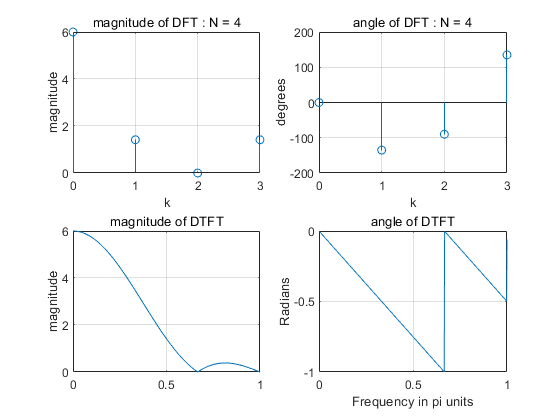

% DTFT
n = 0:3;
x = [1,2,2,1];
k = 0:500;
w = k*(pi/500);
DTFT_X = x * (exp(-j*pi/500)) .^ (n'*k);
% DTFT_X = 1 + 2*(exp(-j*w)) + 2*(exp(-2*j*w)) + 1*(exp(-3*j*w))
mag_dtft = abs(DTFT_X);
ang_dtft = angle(DTFT_X);
% DFT
N = 4;
X = dft(x,N);
magX = abs(X);
angX = angle(X)*180/pi;
figure()
subplot(2,2,1), stem(n, magX);
grid on;
title("magnitude of DFT : N = 4");
xlabel("k");
ylabel("magnitude");
subplot(2,2,2), stem(n, angX);
title("angle of DFT : N = 4");
xlabel("k");
ylabel("degrees");
grid on;
subplot(2,2,3), plot(k/500, mag_dtft);
title("magnitude of DTFT");
ylabel("magnitude");
grid on;
subplot(2,2,4), plot(k/500, ang_dtft/pi);
title("angle of DTFT");
xlabel("Frequency in pi units");
ylabel("Radians");
grid on;

비교 결과 : DTFT를 수행하였을 때는 이산시간 푸리에 변환을 [0, pi] 사이의 501개 등간격 주파수에서 수치적으로 계산 했다는 것에서부터 먼저 차이가 났다.

DTF는 4점 DFT로서 N값과 n, k값만 존재하면 plot을 할 수 있었지만 DTFT는 식에 따라 주파수가 필수적으로 요구되었다는 차이점이 존재하였다.

또한 DTFT는 각도의 그림이  -pi와 pi 사이에서 불연속 함수로 묘사되었다.

결국 연속인 DTFT에서 이산으로 sampling을 했을 때 이것을 DFT라고 한다.

DFT는 DTFS와 같은 것이다. (하지만 DFT -> finite domain으로 생각 한것(시간적으로 제한이 있는 신호에 대해 Fourier Transform을 한 것, DTFS -> Periodic 신호(주기 Sequence에 대해 정의한 것))

2) 영 채우기를 시행하여 같은 신호에 대해 16점 DFT 및 IDFT를 수행하라.

clear all
%%16점 DFT(by 0채우기 방법)
x = [1,2,2,1,zeros(1,6)];
N = 10;
n = 0:9;
X_16 = dft(x,N);
% 16점 DFT 수행 결과
X_16
% 16점 DFT 수행 이후의 크기와 위상을 나타내어 보았다.
magX_16 = abs(X_16)

magX_16 =     6.0000    4.9798    2.6180    0.4490    0.3820    0.0000    0.3820    0.4490    2.6180    4.9798


angX_16 = angle(X_16)*180/pi

angX_16 =          0  -54.0000 -108.0000 -162.0000  -36.0000 -165.9638   36.0000  162.0000  108.0000   54.0000


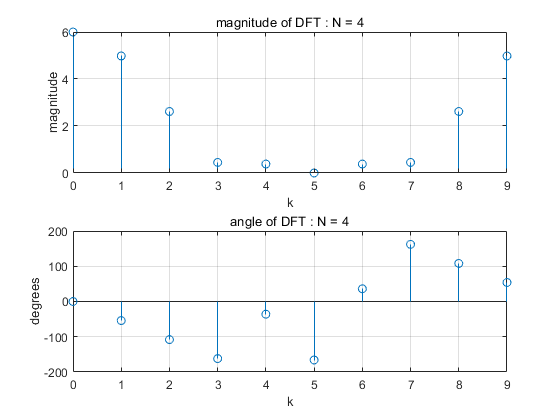

% 16점 DFT를 stem함수를 이용하여 plot해 보았다. 
figure()
subplot(2,1,1), stem(n, magX_16);
grid on;
title("magnitude of DFT : N = 4");
xlabel("k");
ylabel("magnitude");
subplot(2,1,2), stem(n, angX_16);
title("angle of DFT : N = 4");
xlabel("k");
ylabel("degrees");
grid on;

2. (P5.2) DFS의 정의를 사용하여 다음 주기 신호의 DFS 계수를 구하고, MATLAB을 사용하여 검증하라.

1) $\tilde{x_1 } \left(n\right)=\left\lbrace 4,1,-1,1\right\rbrace ,N=4$

1.1 정의를 사용하여 구한 DFS 계수

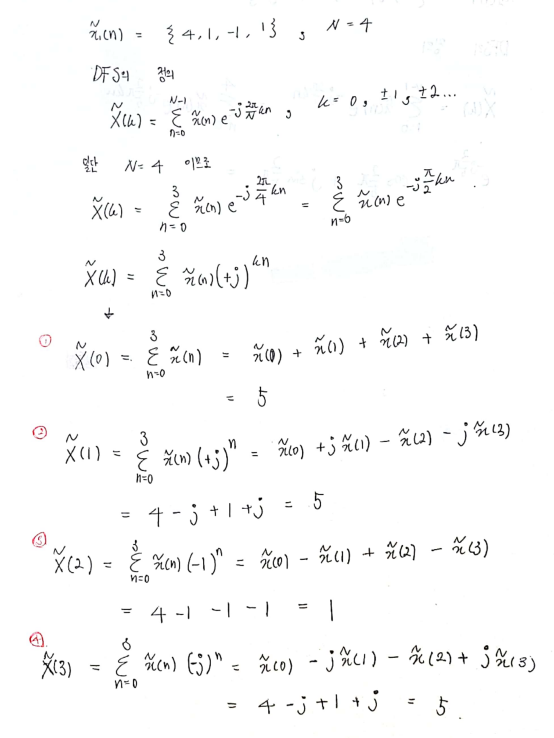

% 직접 값을 비교하여 검증해보았다.
x1 = [4, 1, -1, 1];
N = 4;
Xk = dfs(x1,N)

Xk =    5.0000 + 0.0000i   5.0000 + 0.0000i   1.0000 - 0.0000i   5.0000 + 0.0000i


2) $\tilde{x_2 } \left(n\right)=\left\lbrace 1,0,-1,-1,0\right\rbrace ,N=5$

1.2.1 정의를 사용하여 구한 DFS 계수

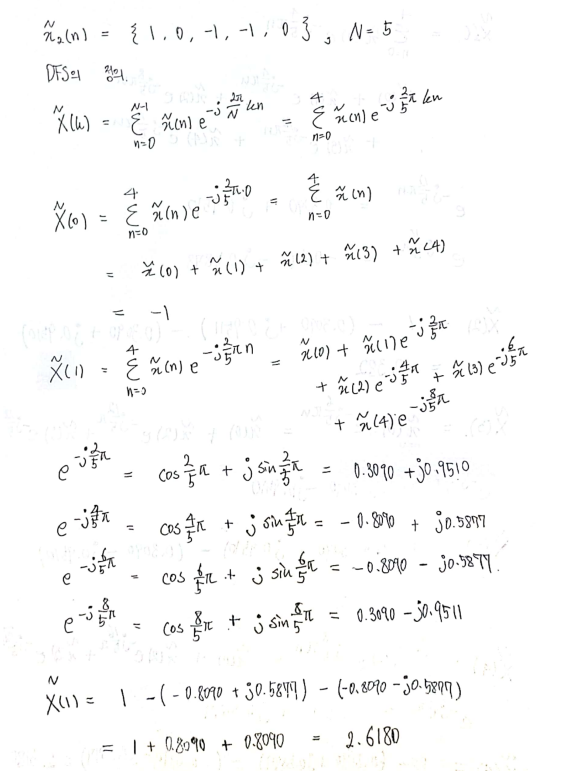

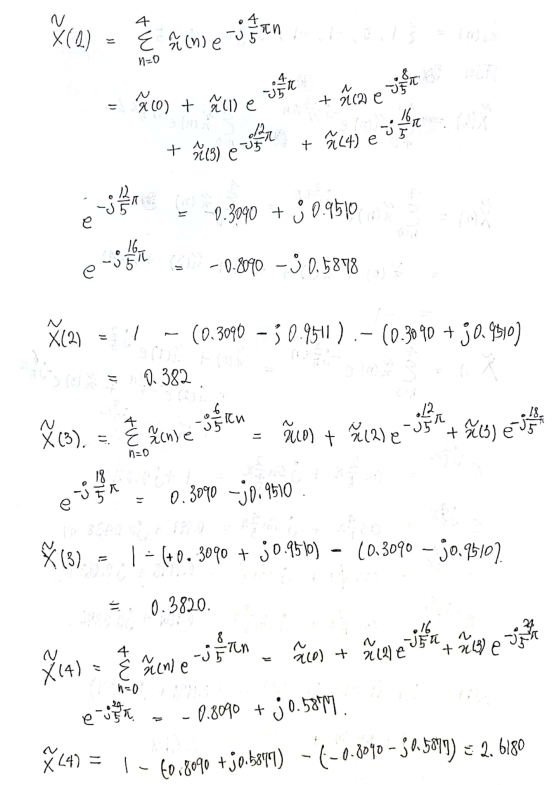

% Matlab으로 구현하고 검증해보았다.
x1 = [1, 0, -1, -1, 0];
N = 5;
Xk = dfs(x1,N)

Xk =   -1.0000 + 0.0000i   2.6180 + 0.0000i   0.3820 - 0.0000i   0.3820 + 0.0000i   2.6180 + 0.0000i


3.  (P5.10) 아래와 같이 주어진 유한 길이 신호를 고려하자.


$$x\left(n\right)=\left\lbrace \begin{array}{ll}
{\textrm{sinc}}^2 \left\lbrace \frac{\left(n-50\right)}{2}\right\rbrace  & 0\le n\le 100\\
0 & \textrm{otherwise}
\end{array}\right.$$


1) x(n)의 DFT X(k)를 구하라. (stem 함수를 사용하여) 그것의 크기 및 위상 그래프를 그려라. 

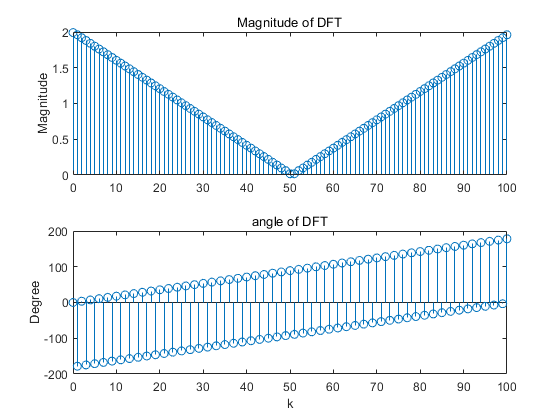

clear all
n = 0:100;
x1 = sinc((n-50)/2).^2;
N = length(x1);
% dft함수를 이용한 DFT계산
Xk = dft(x1,N);
% k별로 변화하는 위상과 크기 그래프를 그렸다.
k = 0:N-1;
mag_dft = abs(Xk);
ang_dft = angle(Xk)*180/pi; 
figure()
subplot(2,1,1), stem(k,mag_dft);
ylabel('Magnitude');
title('Magnitude of DFT');
subplot(2,1,2);
stem(k,ang_dft);
xlabel('k');
ylabel('Degree');
title('angle of DFT');

2) MATLAB을 사용하여 x(n)의 DTFT $X\left(e^{j\omega } \right)$의 크기 및 위상 그래프를 그려라.

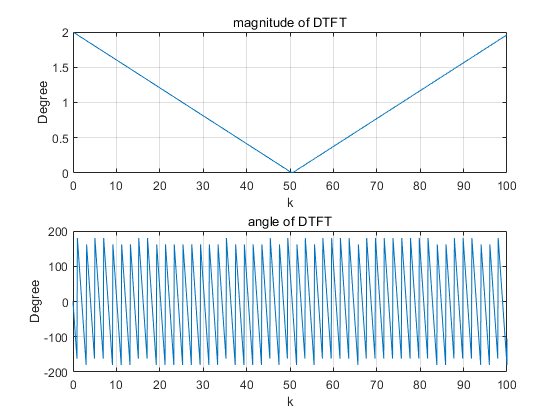

[X,w] = freqz(x1,1,1000,'whole');
% X = x1 * (exp(-j*pi/100)).^(n'*k);
% DTFT의 주파수응답을 표현하기 위하여 디지털 필터의 주파수 응답을 나타내는 freqz함수를 사용하여 DTFT를 표현하였다.
mag_X = abs(X);
pha_X = angle(X)*180/pi; 
Dw = 2*pi/N;  % 후에 이를 DFT 그래프와 동일선상에서 표시해주기 위해 범위를 조정해주는 것이다.
figure()
subplot(2,1,1), plot(w/Dw,mag_X);
xlabel('k');
ylabel('Degree');
title('magnitude of DTFT');
grid on
axis([0 100 0 2]);
subplot(2,1,2), plot(w/Dw,pha_X);
xlabel('k');
ylabel('Degree');
title('angle of DTFT');
grid on
axis([0 100 -200 200]);

3) 위 DFT는 $X\left(e^{j\omega } \right)$의 샘플링된 변형임을 검증하라. hold 함수 (hold on;) 를 사용해서 두 그래프를 합치도록 한다.

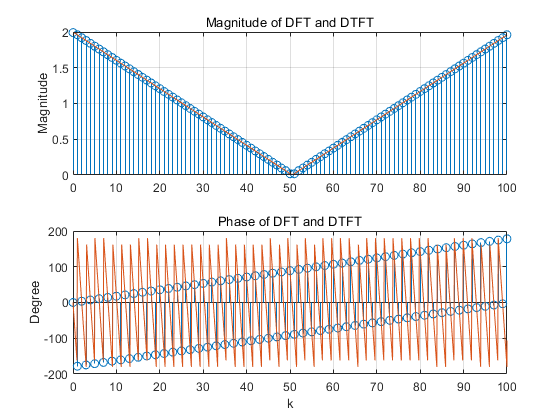

figure()
subplot(2,1,1), stem(k,mag_dft);
ylabel('Magnitude');
title('Magnitude of DFT and DTFT');
hold on;
subplot(2,1,2);
stem(k,ang_dft);
xlabel('k');
ylabel('Degree');
title('Phase of DFT and DTFT');
hold on;
subplot(2,1,1); plot(w/Dw,mag_X);
grid on;
axis([0 100 0 2]);
hold off;
subplot(2,1,2); plot(w/Dw,pha_X);
grid on;
axis([0 100 -200 200]);
hold off;

그래프를 보았을 때 DFT는 결국 DTFT의 샘플링된 변형이라는 것을 명확하게 알 수 있다.

4) DFT $X\left(k\right)$로부터 DTFT $X\left(e^{j\omega } \right)$를 재구성할 수 있는가? 가능하다면, 재구성에 필요한 보간 공식을 구하라. 가능하지 않다면, 그 이유를 기술하라.

재구성할 수 있다. 재구성에 필요한 보간 공식을 구해본다면.

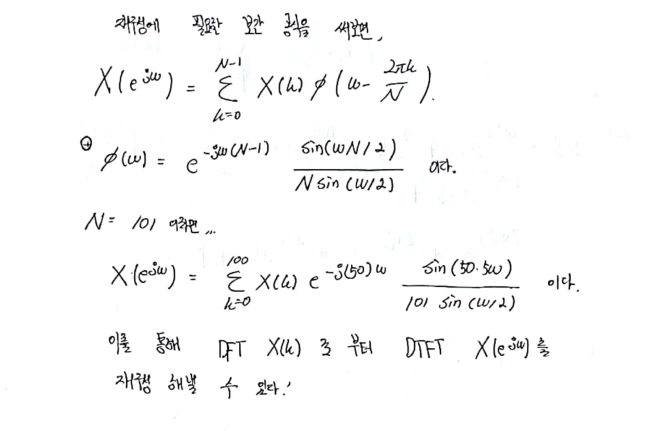

함수

function [Xk] = dfs(xn,N)
n = [0:1:N-1];
k = [0:1:N-1];
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN .^ nk;
Xk = xn * WNnk;
end

%% DTF
function [Xk] = dft(xn,N)
n = [0:1:N-1];
k = [0:1:N-1];
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN .^ nk;
Xk = xn * WNnk;
end

%% IDFT
function [xn] = idft(Xk,N)
n = [0:1:N-1];
k = [0:1:N-1];
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN .^ (-nk);
xn = (Xk * WNnk)/N;
end

